开始接收数据...


接收完毕！


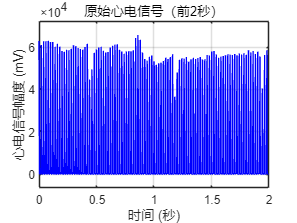

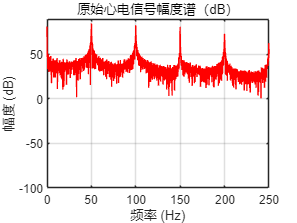

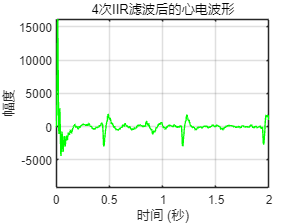

检测到 12 个R波。


平均心率：91.07 bpm


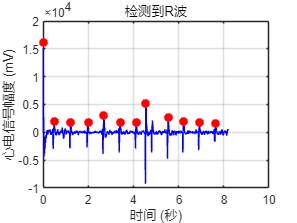

%MATLAB处理原始信号并输出心率
% 陷波器 * 2 + 低通 + 高通
portName = "COM6";
baudRate = 230400;
numPoints = 4096;
Fs = 500;
% 安全串口读取逻辑
try
    % 如果串口已经存在则先关闭
    if exist('s', 'var')
        clear s
    end

    % 创建串口对象
    s = serialport(portName, baudRate);
    flush(s);

    % 读取数据
    disp("开始接收数据...");
    dataBuffer = zeros(1, numPoints);
    for i = 1:numPoints
        line = readline(s);                  
        dataBuffer(i) = str2double(line);   
    end
    disp("接收完毕！");
%%%%%%%%%%%%%%%%%%% ==== 原始心电信号 ==== &&&&&&&&&&&&&&&&&&&&&
    % 时间轴
    t = (0:numPoints-1) / Fs;

    % 显示前2秒
    showPoints = Fs * 2;
    t_show = t(1:showPoints);
    v_show = dataBuffer(1:showPoints);

    % 绘图
    figure;
    plot(t_show, v_show, 'b');
    xlabel('时间 (秒)');
    ylabel('心电信号幅度 (mV)');
    title('原始心电信号（前2秒）');
    grid on;

    % 合理的纵坐标缩放
    margin = 0.1 * (max(v_show) - min(v_show) + eps);
    ylim([min(v_show)-margin, max(v_show)+margin]);

%%%%%%%%%%%% ==== 幅度谱（以 dB 显示） ==== &&&&&&&&&&&&&&&&&&&&&
    N = length(dataBuffer);               % 点数
    Y = fft(dataBuffer);                 % FFT
    P2 = abs(Y / N);                     % 双边谱
    P1 = P2(1:N/2+1);                    % 单边谱
    P1(2:end-1) = 2 * P1(2:end-1);       % 除DC和Nyquist以外乘2
    f = Fs * (0:(N/2)) / N;              % 频率轴（Hz）
    % 转换为 dB 幅度谱
    P1_dB = 20 * log10(P1 + eps);        % 加 eps 防止 log(0)
    figure;
    plot(f, P1_dB, 'r');
    xlabel('频率 (Hz)');
    ylabel('幅度 (dB)');
    title('原始心电信号幅度谱（dB）');
    grid on;
    xlim([0 100]);                       % 限制在心电有效频率范围
    ylim([-100, max(P1_dB)+5]);          % 设置合适的 dB 范围
    % 可选：只显示前250 Hz（心电信号频率范围）
    xlim([0 250]);

%%%%%%%%%%%%%%%%% 定义滤波器系数  %%%%%%%%%%%%%%%%%%%%%
a_notch50 = [1.0, -1.52226142, 0.88161859];
b_notch50 = [0.9408093, -1.52226142, 0.9408093];

a_notch100 = [1.0, -0.54871515, 0.77567951];
b_notch100 = [0.88783976, -0.54871515, 0.88783976];

a_lowpass = [1.0, -1.64745998, 0.70089678];
b_lowpass = [0.0133592, 0.0267184, 0.0133592];

a_highpass = [1.0, -1.91119707, 0.91497583];
b_highpass = [0.95654323, -1.91308645, 0.95654323];

% 原始信号：dataBuffer
filtered1 = iir_filter(dataBuffer, b_notch50, a_notch50);
filtered2 = iir_filter(filtered1, b_notch100, a_notch100);
filtered3 = iir_filter(filtered2, b_lowpass, a_lowpass);
filtered_final = iir_filter(filtered3, b_highpass, a_highpass);

figure;
plot(t_show, filtered_final(1:showPoints), 'g');
xlabel('时间 (秒)');
ylabel('幅度');
title('4次IIR滤波后的心电波形');
grid on;
ylim([min(filtered_final)-0.1, max(filtered_final)+0.1]);


%%%%%%%%%%%%%%% ==IIR消除基线偏移==%%%%%%%%%%%%%%%%%
% ecgData = dataBuffer;
% 
% % 定义滤波器系数
% a = 0.992;
% b = [1, -1];
% a_filter = [1, -a];
% ecg_filtered = filter(b, a_filter, ecgData);
% 
% % 时间轴
% t = (0:length(ecgData)-1) / Fs;
% 
% % 显示前2秒
% showPoints = Fs * 2;
% t_show = t(1:showPoints);
% v_show = ecg_filtered(1:showPoints);
% 
% % 绘图
% figure;
% plot(t_show, v_show, 'r');
% xlabel('时间 (秒)');
% ylabel('滤波后心电信号幅度 (mV)');
% title('滤波后心电信号（前2秒）');
% grid on;
%%%%%%%%%%%%%%% ==FIR消除工频干扰==%%%%%%%%%%%%%%%%%
% filtered_ecg = filter(Hd_FIR2, ecg_filtered);
% 
% % 取前2秒显示
% v_show_fir = filtered_ecg(1:showPoints);
% 
% % 绘图显示 FIR 滤波后波形
% figure;
% plot(t_show, v_show_fir, 'g');
% xlabel('时间 (秒)');
% ylabel('滤波后心电信号幅度 (mV)');
% title('FIR滤波后心电信号（去除工频干扰）');
% grid on;
% 
% % 合理的纵坐标缩放
% margin = 0.1 * (max(v_show_fir) - min(v_show_fir) + eps);
% ylim([min(v_show_fir)-margin, max(v_show_fir)+margin]);
% 
% % 合理的纵坐标缩放
% margin = 0.1 * (max(v_show) - min(v_show) + eps);
% ylim([min(v_show)-margin, max(v_show)+margin]);

% ========== 新增：显示滤波后信号的幅度谱 ==========
% 计算FFT
% N = length(filtered_ecg);               % 点数
% Y = fft(filtered_ecg);                 % FFT
% P2 = abs(Y / N);                       % 双边谱
% P1 = P2(1:N/2+1);                      % 单边谱
% P1(2:end-1) = 2 * P1(2:end-1);         % 除DC和Nyquist以外乘2
% f = Fs * (0:(N/2)) / N;                % 频率轴（Hz）
% 
% % 转换为 dB 幅度谱
% P1_dB = 20 * log10(P1 + eps);          % 加 eps 防止 log(0)
% 
% % 绘制幅度谱
% figure;
% plot(f, P1_dB, 'r');
% xlabel('频率 (Hz)');
% ylabel('幅度 (dB)');
% title('FIR滤波后心电信号幅度谱（dB）');
% grid on;
% xlim([0 100]);                         % 限制在心电有效频率范围
% ylim([-100, max(P1_dB)+5]);            % 设置合适的 dB 范围
% % 可选：只显示前250 Hz（心电信号频率范围）
% xlim([0 250]);

%%%%%%%%%%%%%%% ==检测R波计算心率==%%%%%%%%%%%%%%%%%
% --- R波检测：找到主峰（正向） ---
[peaks, locs] = findpeaks(filtered_final, 'MinPeakHeight', mean(filtered_final)+std(filtered_final), ...
                                          'MinPeakDistance', round(0.4*Fs));  % 至少间隔0.4秒一个R波（对应150bpm）

% --- 计算RR间期 ---
RR_intervals = diff(locs) / Fs;  % 秒

% --- 计算心率（bpm） ---
HR = 60 ./ RR_intervals;
HR_avg = mean(HR);  % 平均心率

% --- 显示结果 ---
fprintf('检测到 %d 个R波。\n', length(peaks));
fprintf('平均心率：%.2f bpm\n', HR_avg);

% --- 可视化 ---
t = (0:length(filtered_final)-1)/Fs;
figure;
plot(t, filtered_final, 'b'); hold on;
plot(locs/Fs, peaks, 'ro', 'MarkerFaceColor','r');  % R波标记
xlabel('时间 (秒)');
ylabel('心电信号幅度 (mV)');
title(sprintf('检测到R波'));
grid on;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
catch ME
    warning('发生错误：%s', ME.message);
end


% 无论是否出错，最后释放串口资源
if exist('s', 'var')
    clear s
end


function y = iir_filter(x, b, a)
% x: 输入信号（向量）
% b, a: 滤波器系数
% y: 输出信号（向量）
    y = zeros(size(x));
    for n = 3:length(x)
        y(n) = (b(1)*x(n) + b(2)*x(n-1) + b(3)*x(n-2) ...
               - a(2)*y(n-1) - a(3)*y(n-2)) / a(1);
    end
end